# Gaussian Filters

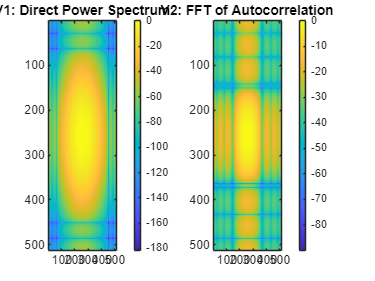

% 2-D Gaussian Power Spectrum Comparison

kernel = 9;
sigma = 1.5;
mask = fspecial('gaussian', kernel, sigma);

title_str = sprintf('Gaussian %dx%d, \\sigma=%.2f', kernel, kernel, sigma);

% % Generate a 2D Gaussian mask
% [x, y] = meshgrid(-(kernel_size - 1)/2 : (kernel_size - 1)/2, -(kernel_size - 1)/2 : (kernel_size - 1)/2);
% mask = exp(-(x.^2 + y.^2) / (2 * sigma^2));
% mask = mask / sum(mask(:));  % Normalize

% Assume mask is a Gaussian 2D kernel
NFFT = 512;

% Direct Power Spectrum (V1)
SRmask_v1 = abs(fftshift(fft2(mask, NFFT, NFFT))).^2;
ps_gauss2d_v1 = SRmask_v1(:, NFFT/2);

% Power Spectrum via Autocorrelation (V2)
% Use full convolution and ensure proper centering
Rmask = conv2(mask, mask, 'same');  % Full autocorrelation

% Apply 2D FFT on the centered autocorrelation
SRmask_v2 = abs(fftshift(fft2(Rmask, NFFT, NFFT)));
ps_gauss2d_v2 = SRmask_v2(:, NFFT/2);

% figure, 
% imagesc(SRmask_v1 - SRmask_v2)
% title('Delta Before'), colorbar

% Normalize both spectra for fair comparison
SRmask_v1 = SRmask_v1 / max(SRmask_v1(:));
SRmask_v2 = SRmask_v2 / max(SRmask_v2(:));

% figure, 
% imagesc(SRmask_v1 - SRmask_v2)
% title('Delta After'), colorbar

% Plotting results
figure;
subplot(1, 2, 1);
imagesc(pow2db(SRmask_v1)); 
title('V1: Direct Power Spectrum');
colorbar;

subplot(1, 2, 2);
imagesc(pow2db(SRmask_v2)); 
title('V2: FFT of Autocorrelation');
colorbar;

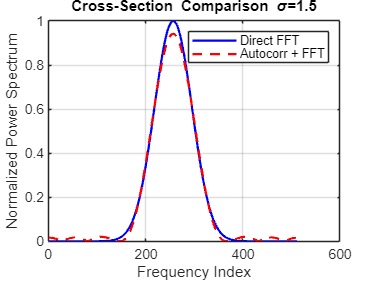


% Plot cross-sections for comparison
figure;
plot(ps_gauss2d_v1, 'b', 'LineWidth', 1.5); hold on;
plot(ps_gauss2d_v2, 'r--', 'LineWidth', 1.5);
legend('Direct FFT', 'Autocorr + FFT');
xlabel('Frequency Index');
ylabel('Normalized Power Spectrum');
title(['Cross-Section Comparison \sigma=',num2str(sigma)]);
grid on;

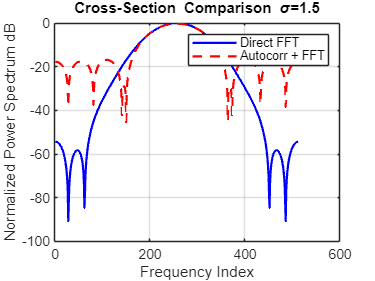


figure;
plot(pow2db (ps_gauss2d_v1), 'b', 'LineWidth', 1.5); hold on;
plot(pow2db (ps_gauss2d_v2), 'r--', 'LineWidth', 1.5);
legend('Direct FFT', 'Autocorr + FFT');
xlabel('Frequency Index');
ylabel('Normalized Power Spectrum dB');
title(['Cross-Section Comparison \sigma=',num2str(sigma)]);
grid on;

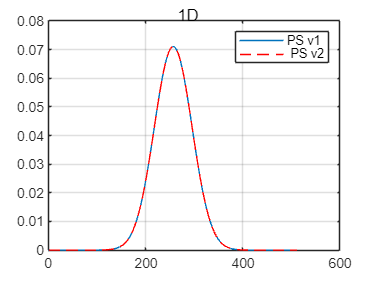


% 1-D version

gauss1d = mask(:,5); % mask(5,:)

% Simple
ps_gauss1d_v1 = abs(fftshift(fft(gauss1d, NFFT))).^2;

% With xcorr
gauss1d_xcorr = xcorr(gauss1d);

ps_gauss1d_v2 = abs(fftshift(fft(gauss1d_xcorr, NFFT)));

figure, 
sgtitle('1D')
plot(ps_gauss1d_v1, 'DisplayName','PS v1')
hold on
plot(ps_gauss1d_v2, 'r--', 'DisplayName', ' PS v2')
legend
grid on

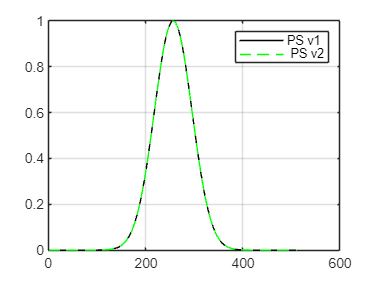


figure, 
plot(ps_gauss1d_v1 /max(ps_gauss1d_v1), 'k','DisplayName','PS v1')
hold on
plot(ps_gauss1d_v2/max(ps_gauss1d_v2), 'g--', 'DisplayName', ' PS v2')
legend
grid on

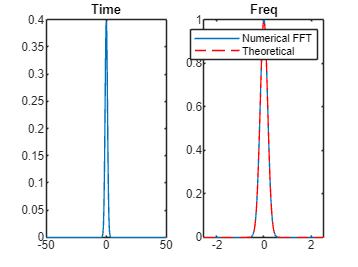

% 1D THEORETICAL
N = 512;
sigma = 1;
t = linspace(-50, 50, N);  % Spatial domain
dt = min(diff(t)); 

g_t = exp(-t.^2 / (2*sigma^2)) / (sqrt(2*pi)*sigma);
% g_t = 1 - g_t;

G_f = abs(fftshift(fft(g_t)));
freq = (-N/2:N/2-1)/N/dt;

G_f_theo = exp(-2*(pi*sigma*freq).^2);

figure, 
subplot(1,2,1)
plot(t, g_t), title('Time')

subplot(1,2,2)
plot(freq, G_f*dt), title('Freq')
hold on;
plot(freq, G_f_theo, 'r--');
legend('Numerical FFT', 'Theoretical');

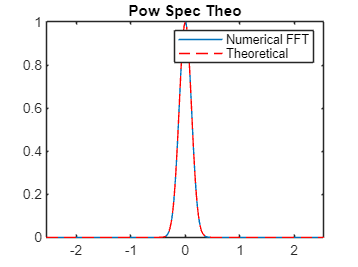



ps_G_f = G_f.^2 ;
ps_G_f_theo = G_f_theo.^2;

figure, 
plot(freq, ps_G_f/max(ps_G_f)), title('Pow Spec Theo')
hold on;
plot(freq, ps_G_f_theo/max(ps_G_f_theo), 'r--');
legend('Numerical FFT', 'Theoretical');

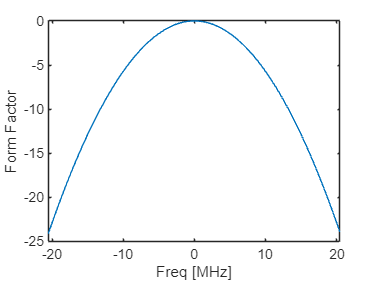

c0 = 1540;
dx = 0.3e-3 /16;
ft_space = c0/2/dx;

freq_s = ((-NFFT/2):(NFFT/2-1))/NFFT*ft_space;
% ff = exp(-sigma^2 * dx*dx* (2*pi/c0)^2 * freq_s.^2 ); %ok
% ff = exp(-4* dx^2 * (2*pi/c0)^2 * freq_s.^2 ); %ok
ff = exp(-sigma^2 *(2*pi/c0 *freq_s *dx).^2 ); %ok


figure, 
plot(freq_s*1e-6, pow2db(ff))
xlabel('Freq [MHz]')
ylabel('Form Factor')

### Theoretical n(f)

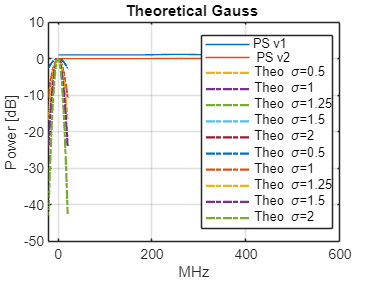

c0 = 1540;
dx = 0.3e-3 /16;
ft_space = c0/2/dx;
NFFT = 512;

freq_s = ((-NFFT/2):(NFFT/2-1))/NFFT*ft_space; %[Hz]
freq_MHz = freq_s*1e-6;
list_sigma = [0.5 1 1.25 1.5 2];

figure(18) 
for ss = 1:length(list_sigma)

    sigma = list_sigma(ss);
    f_theo = exp(-sigma^2 *(2*pi/c0 *freq_s *dx).^2 ); %ok
    
    plot(freq_MHz, 10*log10(f_theo), '-.', 'LineWidth', 1.5, 'DisplayName', ['Theo \sigma=', num2str(sigma)]);
    hold on, grid on,
    title('Theoretical Gauss ')
legend('Location', 'Best')
xlabel('MHz'); ylabel('Power [dB]');
grid on;
end

### Test Modulation

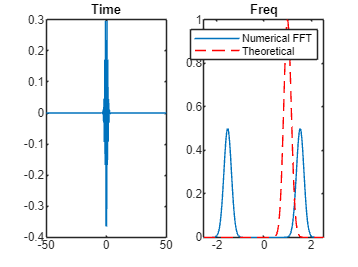


% 1D THEORETICAL
N = 512;
sigma = 1;
t = linspace(-50, 50, N);  % Spatial domain
dt = min(diff(t)); 

g_t = exp(-t.^2 / (2*sigma^2)) / (sqrt(2*pi)*sigma);
g_t = g_t .* cos(2*pi*70*t);

G_f = abs(fftshift(fft(g_t)));
freq = (-N/2:N/2-1)/N/dt;

G_f_theo = exp(-2*(pi*sigma*(freq-1)).^2);

figure, 
subplot(1,2,1)
plot(t, g_t), title('Time')

subplot(1,2,2)
plot(freq, G_f*dt), title('Freq')
hold on;
plot(freq, G_f_theo, 'r--');
legend('Numerical FFT', 'Theoretical');

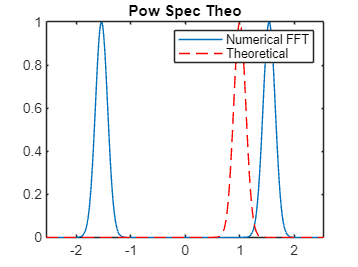



ps_G_f = G_f.^2 ;
ps_G_f_theo = G_f_theo.^2;

figure, 
plot(freq, ps_G_f/max(ps_G_f)), title('Pow Spec Theo')
hold on;
plot(freq, ps_G_f_theo/max(ps_G_f_theo), 'r--');
legend('Numerical FFT', 'Theoretical');

### Test Modulation 2D

## Spatial Frequency to Temporal Frequency


$$\frac{f}{{\hat{f} }_x }=c_0 \to {\hat{k} }_x =\frac{2\pi \;f}{c_0 }$$


Discretize

- 
$${\hat{f} }_x \in \left\lbrack -\frac{1}{2\cdot \textrm{dx}},\frac{1}{2\cdot \textrm{dx}}\;\right\rbrack \to f=\left\lbrack -\frac{c_0 }{2\cdot \textrm{dx}},\frac{c_0 }{2\cdot \textrm{dx}}\;\right\rbrack$$


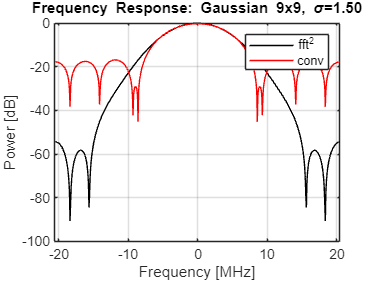

% Compute spatial frequency
dx = 0.3e-3 /16; % technically dy dx of kgrid element_pitch / element_width

c0 = 1540;
ft_space = c0/2/dx;
freq_s = ((-NFFT/2):(NFFT/2-1))/NFFT * ft_space * 1e-6; % [MHz]

figure, 
plot(freq_s, pow2db(ps_gauss2d_v1), 'k', 'DisplayName', 'fft^2');
hold on;
plot(freq_s, pow2db(ps_gauss2d_v2), 'r', 'DisplayName','conv')
grid on;

xlabel('Frequency [MHz]');
ylabel('Power [dB]');
title(['Frequency Response: ', title_str]);
legend()